# Reserve Variance Live Script 3

## Change Folder

cd("F:\OneDrive - Queensland University of Technology\Research " + ...
    "Assistant Work (OD)\Reserve Variance (OD)\Code")

cd("C:\Users\sowen\OneDrive - Queensland University of Technology\" + ...
    "Research Assistant Work (OD)\Reserve Variance (OD)\Code")

## Load Data

if ~exist("workspaceVarReserveVariance", 'var')
    load matlabReserveVariance.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarReserveVariance", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabReserveVariance.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Results From New Study Areas

Just One More Study Area xd

Calclute Summary Statistics

ANZIAM Fish Figure

Understanding Differences Between Regions

## Assumptions / Notes

## Results From New Study Areas

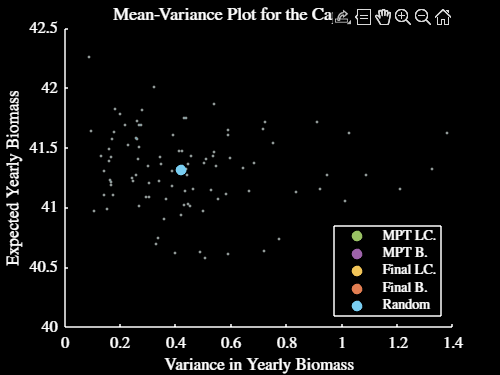

% do the results from the Cape first
figure
plotFinalResults(simOutCellCape, "Cape")
setFontSize(13)
% ylim([50, 70])
% figResize(1.2)
lightFig()
saveFig("meanVarSpaceCape")
darkFig()
saveFig("meanVarSpaceCapeDM")


% what in God's name is going on here - nvm, I just had to run the below
% and it fixed it, had an error in my runMPASimulation() code that meant
% the MPAs didn't get set properly so crisis averted

randStruct.randType = "sequence";
for i = 1:length(simOutCellCape)
    simOutCellCape{i} = rerunMPASimulation2(simStructFin, ...
        areaStructCape, areaStructGBR, specStructCT, randStruct, ...
        actionStructFin, simOutCellCape{i});
end

randStruct.randType = "sequence";
for i = 1:length(simOutCellCairns)
    simOutCellCairns{i} = rerunMPASimulation2(simStructFin, ...
        areaStructCairns, areaStructGBR, specStructCT, randStruct, ...
        actionStructFin, simOutCellCairns{i});
end

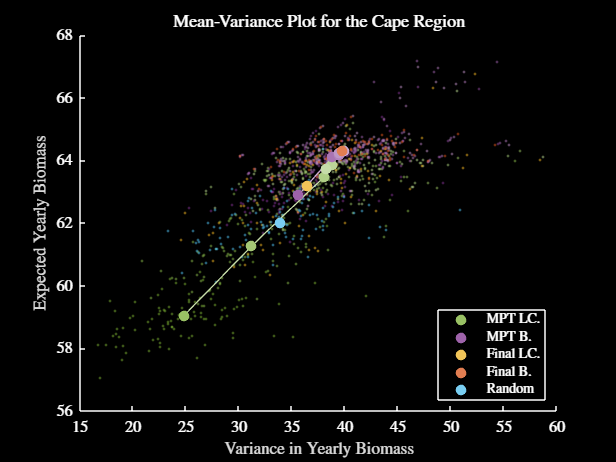

figure
plotFinalResults(simOutCellCape, "Cape")
setFontSize(13)
% ylim([50, 70])
% figResize(1.2)
lightFig()
saveFig("meanVarSpaceCape")
darkFig()
saveFig("meanVarSpaceCapeDM")

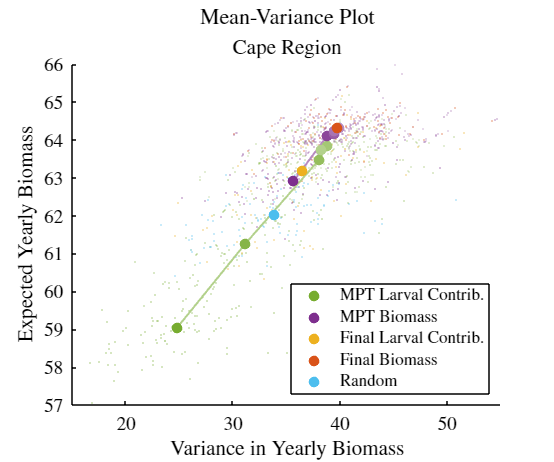

% make another one for my presentation
figure
plotFinalResults(simOutCellCape, "Cape", "pres")
setFontSize(16)
% ylim([50, 70])
axis([15, 55, 57, 66])
figResize(1, 0.9)
lightFig()
saveFig("meanVarSpaceCapePP")

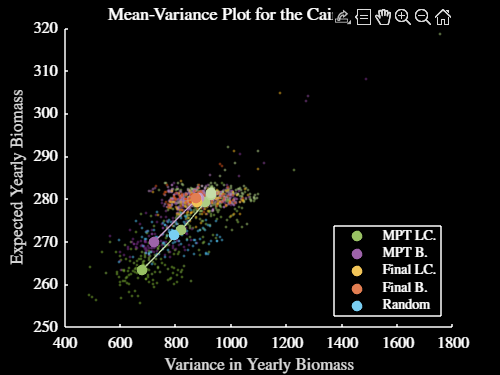

figure
plotFinalResults(simOutCellCairns, "Cairns")
setFontSize(13)
% ylim([50, 70])
% figResize(1.2)
lightFig()
saveFig("meanVarSpaceCairns")
darkFig()
saveFig("meanVarSpaceCairnsDM")

## Just One More Study Area xd

% load in the Australia outline
ausOutline = shaperead("../Data/australia_Australia_Country_Boundary" + ...
    "/australia_Australia_Country_Boundary.shp");

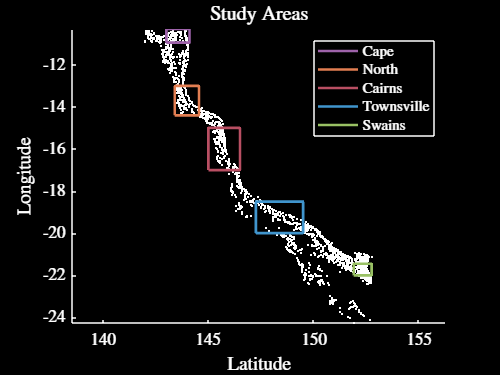

figure
hold on
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', ...
    getColour('p'), 'LineWidth', 2)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', ...
    getColour('o'), 'LineWidth', 2)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', ...
    getColour('r'), 'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', ...
    getColour('b'), 'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', ...
    getColour('g'), 'LineWidth', 2)
% plotGBRShape(GBRShapeCT)
plot(centroidsCT(:, 1), centroidsCT(:, 2), 'k.', 'MarkerSize', 4)
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', ...
    getColour('p'), 'LineWidth', 2)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', ...
    getColour('o'), 'LineWidth', 2)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', ...
    getColour('r'), 'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', ...
    getColour('b'), 'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', ...
    getColour('g'), 'LineWidth', 2)
axis equal
title("Study Areas")
xlabel("Latitude")
ylabel("Longitude")
legend("Cape", "North", "Cairns", "Townsville", "Swains")
setFontSize(14)
darkFig()

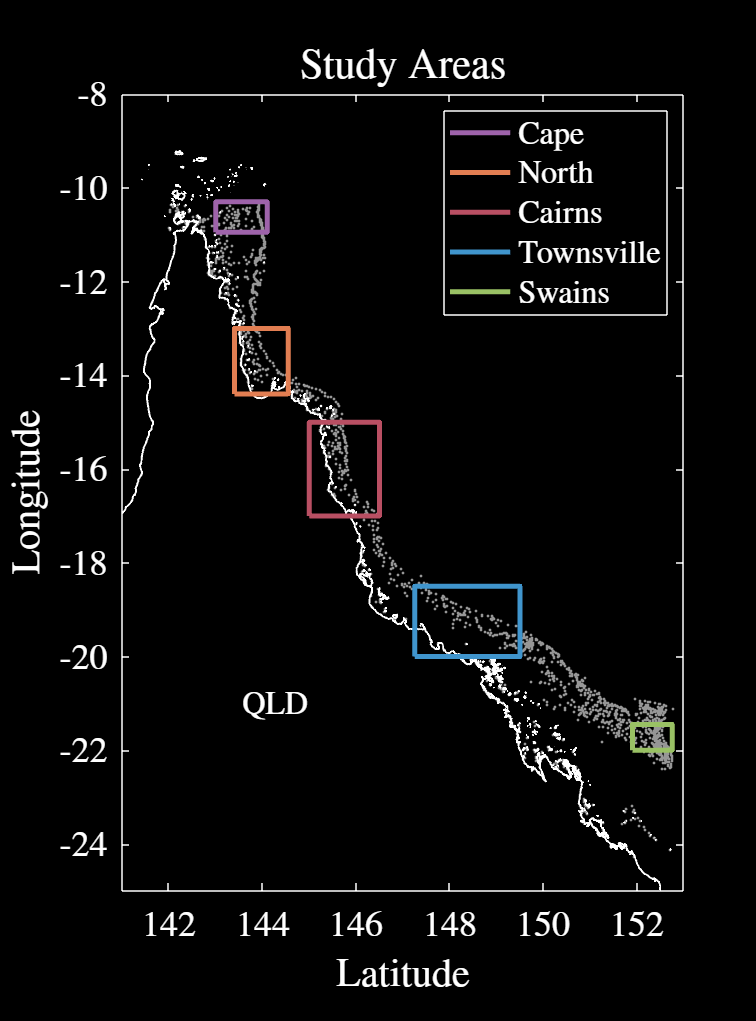

% making another and saving for the presentation
figure
hold on
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', ...
    getColour('p'), 'LineWidth', 2.5)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', ...
    getColour('o'), 'LineWidth', 2.5)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', ...
    getColour('r'), 'LineWidth', 2.5)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', ...
    getColour('b'), 'LineWidth', 2.5)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', ...
    getColour('g'), 'LineWidth', 2.5)
% plotGBRShape(GBRShapeLL)
plot(centroidsCT(:, 1), centroidsCT(:, 2), '.', 'Color', ...
    2.25 * [0.2, 0.2, 0.2], 'MarkerSize', 3.5)
plot(ausOutline.X, ausOutline.Y, 'k', 'LineWidth', 1)
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', ...
    getColour('p'), 'LineWidth', 2.5)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', ...
    getColour('o'), 'LineWidth', 2.5)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', ...
    getColour('r'), 'LineWidth', 2.5)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', ...
    getColour('b'), 'LineWidth', 2.5)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', ...
    getColour('g'), 'LineWidth', 2.5)
axis equal
axis([141, 153, -25, -8])
title("Study Areas")
xlabel("Latitude")
ylabel("Longitude")
% set(gca,'XTickLabel',[]);
% set(gca,'YTickLabel',[]);
% h=gca; h.XAxis.TickLength = [0 0];
% h=gca; h.YAxis.TickLength = [0 0];
box on
text(143.5, -21, "QLD")
legend("Cape", "North", "Cairns", "Townsville", "Swains")
% setFontSize(28)
setFontSize(20)
figResize(1.8)
lightFig()
% saveFig("studyAreasPP")
saveFig("studyAreas")
darkFig()
saveFig("studyAreasDM")

% maybe don't do that for now, seems a bit dumb really to just keep
% chucking in new study areas

## Calclute Summary Statistics

% let's look at some summary statistics for all of the methods methinks

% want to look at:

% slope between the expected value and variance

% difference between best variance reduction for larval contribution and
% biomass

% difference between the best expected value increase between biomass only
% and larval contribution

% could also look into some other stuff too in order to understand perhaps
% why things do better in some regions than others - could do max min
% median CV for connectivity

calcMPASummary()

runMPASimulation()

simOutCellCape{5}.objFuncE

ans = "MPTBiom"

summaryTable = calcMPASummary(simOutCellCape, "Cape");
summaryTable(2, :) = calcMPASummary(simOutCellNorth, "North");
summaryTable(3, :) = calcMPASummary(simOutCellCairns, "Cairns");
summaryTable(4, :) = calcMPASummary(simOutCellTowns, "Townsville");
summaryTable(5, :) = calcMPASummary(simOutCellSwains, "Swains");
summaryTable{6, :} = ["Average", mean(summaryTable{1:5, 2:end}, 1)];
summaryTable

summaryTable = 6×15 table
     studyArea      varRedLCVsB    varRedLCVsR    varRedBVsR    expValDecLCVsR    expValDecBVsR    expValIncBVsLC    expValIncLCVsR    expValIncBVsR    expValIncFBVsB    expValIncNVsR    varIncLCVsR    varIncBVsR    SlopeLC    SlopeB
    ____________    ___________    ___________    __________    ______________    _____________    ______________    ______________    _____________    ______________    _____________    ___________    __________    _______    ______

% checking the slopes above, first for cape
(38 - 24) / (64 - 59)

ans = 2.8000


% now for the north
(440 - 390) / (215 - 208)

ans = 7.1429

ans = 7.1429

## ANZIAM Fish Figure

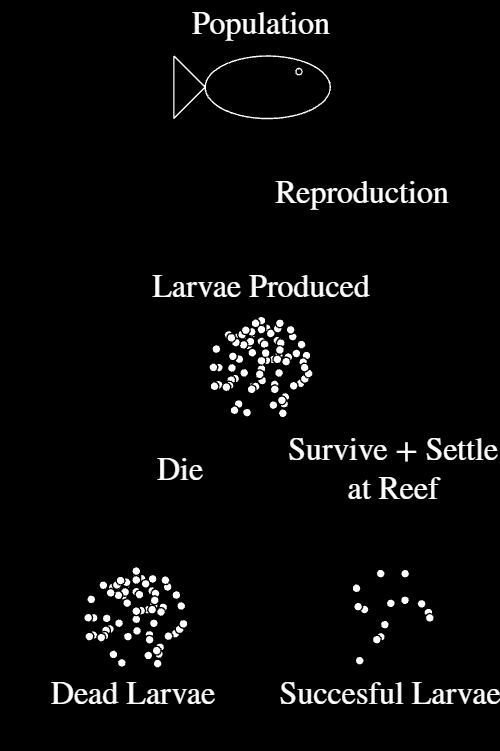

% this is fucking stupid but here we go
fishTail = [0, 0; 0, 1; 0.5, 0.5; 0, 0];
var1 = linspace(0, 2 * pi, 50);
fishBody = [cos(var1)' + 1.5, 0.5 * sin(var1)' + 0.5];
fishEye = [0.05 * cos(var1)' + 2, 0.05 * sin(var1)' + 0.75];
fish = [fishTail; NaN, NaN; fishBody; NaN, NaN; fishEye];

larva = [0.07 * cos(var1)' + 1.4, 0.07 * sin(var1)'];
larvaeProd = [NaN, NaN; larva];
rng(1)
for i = 1:80
    var2 = randi(length(var1));
    larvaeProd = [larvaeProd; NaN, NaN; larva + 0.8 * sqrt(rand()) ...
        * [sin(var1(var2)), cos(var1(var2))]];
end
larvaeProd = [larvaeProd; NaN, NaN];

figure
hold on

% plot the fish
plot(fish(:, 1), fish(:, 2) + 2, 'k')

% plot the original larvae
var3 = find(isnan(larvaeProd(:, 1)));
for i = 1:(length(var3) - 1)
    var4 = (var3(i) + 1):(var3(i + 1) - 1);
    fill(larvaeProd(var4, 1), larvaeProd(var4, 2) - 2, 'w', ...
        'EdgeColor', 'k')
end

% plot the dead larvae
for i = 1:round(0.8 * length(var3))
    var4 = (var3(i) + 1):(var3(i + 1) - 1);
    fill(larvaeProd(var4, 1) - 2, larvaeProd(var4, 2) - 6, 'w', ...
        'EdgeColor', 'k')
end

% plot the alive larvae
for i = round(0.8 * length(var3)):(length(var3) - 1)
    var4 = (var3(i) + 1):(var3(i + 1) - 1);
    fill(larvaeProd(var4, 1) + 2, larvaeProd(var4, 2) - 6, 'w', ...
        'EdgeColor', 'k')
end

% plot da arrows
annotation("arrow", [0.525, 0.525], [0.8, 0.65], 'Color', 'k')
annotation("arrow", [0.525, 0.325], [0.8, 0.65] - 0.38, 'Color', 'k')
annotation("arrow", [0.525, 0.725], [0.8, 0.65] - 0.38, 'Color', 'k')

% plot da text
text(1.4, 3.2, "Population", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "bottom")
text(1.4, -1, "Larvae Produced", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "bottom")
text(-0.65, -7.5, "Dead Larvae", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "bottom")
text(3.45, -7.5, "Succesful Larvae", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "bottom")
text(0.1, -3.6, "Die", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "middle")
text(3.5, -3.6, ["Survive + Settle", "at Reef"], ...
    "HorizontalAlignment", "center", "VerticalAlignment", "middle")
text(3, 0.5, "Reproduction", "HorizontalAlignment", "center", ...
    "VerticalAlignment", "bottom")

setFontSize(30)
axis off
figResize(2)
axis equal
lightFig()
saveFig("larvalContributionDiagram")
darkFig()

## Understanding Differences Between Regions

% need to try and understand why variance reductions were significantly
% larger in the cape, swains and townsville areas comparative to the others

% first, will go and consult the good ol when mpt can work paper, however
% i'm pretty sure there's nothing groundbreaking in there

% they say that outcomes are best when - multiple investments are
% negatively correlated, second-best investments are not that different to
% the best investments in terms of expected value, and when multiple
% investments have a low variability

% not ultra-revolutionary, but good to consider

% first, do I have conMats for each of the regions? - I do, they're in the
% areaStructs however

% alright, what do we want to look at? perhaps CVs first? - fuck it no
% we're doing correlations xd
corrMatCape = calcLarvalCorr(areaStructCape.conMats);
corrMatNorth = calcLarvalCorr(areaStructNorth.conMats);
corrMatCairns = calcLarvalCorr(areaStructCairns.conMats);
corrMatTowns = calcLarvalCorr(areaStructTowns.conMats);
corrMatSwains = calcLarvalCorr(areaStructSwains.conMats);
figure
plotConnectivityStats({corrMatCape(:), corrMatNorth(:), corrMatCairns(:), ...
    corrMatTowns(:), corrMatSwains(:)}, "correlation", ["Cape Region", ...
    "North Region", "Cairns Region", "Townsville Region", "Swains Region"])

ans =   1×5 Axes array:

    Axes    Axes    Axes    Axes    Axes


setFontSize(10)
figResize(1.8)
darkFig()
saveFig("studyAreasTotLarvOutCorrDM")

% difficult to see too much from just the correlations, can't really see
% that much of a difference
clear corrMatCape corrMatNorth corrMatCairns corrMatTowns corrMatSwains

% let's now look at - CV values perhaps
% next, look at the CV values for each area
[meanConnCTCape, stdConnCTCape, ~, ~] ...
    = connectivityAnalysisReef(areaStructCape.conMats, eps);
[meanConnCTNorth, stdConnCTNorth, ~, ~] ...
    = connectivityAnalysisReef(areaStructNorth.conMats, eps);
[meanConnCTCairns, stdConnCTCairns, ~, ~] ...
    = connectivityAnalysisReef(areaStructCairns.conMats, eps);
[meanConnCTTowns, stdConnCTTowns, ~, ~] ...
    = connectivityAnalysisReef(areaStructTowns.conMats, eps);
[meanConnCTSwains, stdConnCTSwains, ~, ~] ...
    = connectivityAnalysisReef(areaStructSwains.conMats, eps);
[meanConnCT, stdConnCT, ~, ~] ...
    = connectivityAnalysisReef(areaStructGBR.conMats, eps);
figure
axVec = plotConnectivityStats({stdConnCTCape ./ meanConnCTCape, ...
    stdConnCTNorth ./ meanConnCTNorth, stdConnCTCairns ...
    ./ meanConnCTCairns, stdConnCTTowns ./ meanConnCTTowns, ...
    stdConnCTSwains ./ meanConnCTSwains, ...
    stdConnCT ./ meanConnCT}, "CVLoc", ["Cape Region", ...
    "Northern GBR Region", "Cairns Region", "Townsville Region", ...
    "Swains Region", "Whole GBR"]);
linkaxes(axVec(1:end-1), "y")
figResize(1.8)
% lightFig()
% saveFig("studyAreasTotLarvOutCVs")
darkFig()
saveFig("studyAreasTotLarvOutCVsDM")


% ok, so CV values offer a key perhaps to this issue - looks like both the
% north and cairns regions have a number of quite low CVs, whereas the
% other have no such thing hmmmmmmmmm

% could it be then that there is just less variability to begin with, and
% so less potential for reductions, along with perhaps the fact that
% randomised approaches are then less likely to choose wildly high reef
% CVs?

% given CVs are tied to both means and SD, let's perhaps have a look at
% those distributions too while we're here
figure
plotConnectivityStats({meanConnCTCape, meanConnCTNorth, ...
    meanConnCTCairns, meanConnCTTowns, meanConnCTSwains, meanConnCT}, ...
    "meanTot", ["Cape Region", "Northern GBR Region", "Cairns Region", ...
    "Townsville Region", "Swains Region", "Whole GBR"]);
figResize(1.8)
% lightFig()
% saveFig("studyAreasTotLarvOutCVs")
darkFig()
saveFig("studyAreasTotLarvOutMeansDM")


% doesn't seem to be much from the means, let's look at the standard
% deviations
figure
plotConnectivityStats({stdConnCTCape, stdConnCTNorth, stdConnCTCairns, ...
    stdConnCTTowns, stdConnCTSwains, stdConnCT}, "stdTot", ["Cape Region", ...
    "Northern GBR Region", "Cairns Region", "Townsville Region", ...
    "Swains Region", "Whole GBR"]);
figResize(1.8)
% lightFig()
% saveFig("studyAreasTotLarvOutCVs")
darkFig()
saveFig("studyAreasTotLarvOutSDsDM")

% some of these mean row sums are stupid high for some dumbass reason
meanConnCT

% idea - could also look at these from the perspective of in strengths and
% degrees too
[meanConnCTCape, stdConnCTCape, ~, ~] ...
    = connectivityAnalysisReef(areaStructCape.conMats, eps, "transpose");
[meanConnCTNorth, stdConnCTNorth, ~, ~] ...
    = connectivityAnalysisReef(areaStructNorth.conMats, eps, "transpose");
[meanConnCTCairns, stdConnCTCairns, ~, ~] ...
    = connectivityAnalysisReef(areaStructCairns.conMats, eps, "transpose");
[meanConnCTTowns, stdConnCTTowns, ~, ~] ...
    = connectivityAnalysisReef(areaStructTowns.conMats, eps, "transpose");
[meanConnCTSwains, stdConnCTSwains, ~, ~] ...
    = connectivityAnalysisReef(areaStructSwains.conMats, eps, "transpose");
[meanConnCT, stdConnCT, ~, ~] ...
    = connectivityAnalysisReef(areaStructGBR.conMats, eps, "transpose");
figure
plotConnectivityStats({stdConnCTCape ./ meanConnCTCape, ...
    stdConnCTNorth ./ meanConnCTNorth, stdConnCTCairns ...
    ./ meanConnCTCairns, stdConnCTTowns ./ meanConnCTTowns, ...
    stdConnCTSwains ./ meanConnCTSwains, ...
    stdConnCT ./ meanConnCT}, "CVLocIn", ["Cape Region", ...
    "Northern GBR Region", "Cairns Region", "Townsville Region", ...
    "Swains Region", "Whole GBR"]);
figResize(1.8)
darkFig()
saveFig("studyAreasTotLarvInCVsDM")


% seems like the north and cairns have slightly lower median values, and
% are spread a little lower, but it's not instantly obvious that there's a
% massive difference here

% given CVs are tied to both means and SD, let's perhaps have a look at
% those distributions too while we're here
figure
axVec = plotConnectivityStats({meanConnCTCape, meanConnCTNorth, ...
    meanConnCTCairns, meanConnCTTowns, meanConnCTSwains, meanConnCT}, ...
    "meanTotIn", ["Cape Region", "Northern GBR Region", "Cairns Region", ...
    "Townsville Region", "Swains Region", "Whole GBR"]);
linkaxes(axVec(1:(end-1)), 'y')
figResize(1.8)
darkFig()
saveFig("studyAreasTotLarvInMeansDM")


% doesn't seem to be much from the means, let's look at the standard
% deviations
figure
axVec = plotConnectivityStats({stdConnCTCape, stdConnCTNorth, ...
    stdConnCTCairns, stdConnCTTowns, stdConnCTSwains, stdConnCT}, ...
    "stdTotIn", ["Cape Region", "Northern GBR Region", ...
    "Cairns Region", "Townsville Region", "Swains Region", "Whole GBR"]);
linkaxes(axVec(1:(end-1)), 'y')
figResize(1.8)
darkFig()
saveFig("studyAreasTotLarvInSDsDM")

clear meanConnCTSwains meanConnCTTowns meanConnCTNorth meanConnCTCape ...
    meanConnCTCairns stdConnCape stdConnCairns stdConnCTSwains ...
    stdConnCTTowns stdConnCTNorth stdConnHaw meanConnHaw meanConnCT ...
    stdConnCT

% second, should consider the influx of larvae from outside the region too
% - this could be smart methinks - tbh, ceebs doing this rn

% look into the populations at each of the reefs
locNamesFull = ["Cape Region", "North Region", "Cairns Region", ...
    "Townsville Region", "Swains Region"];
axVec = plotConnectivityStats({removeNaNs( ...
    simOutCellCape{1}.stdBiomassObs(:) ...
    ./ simOutCellCape{1}.meanBiomassObs(:)), ...
    simOutCellNorth{1}.stdBiomassObs(:) ...
    ./ simOutCellNorth{1}.meanBiomassObs(:), ...
    removeNaNs(simOutCellCairns{1}.stdBiomassObs(:) ...
    ./ simOutCellCairns{1}.meanBiomassObs(:)), ...
    removeNaNs(simOutCellTowns{1}.stdBiomassObs(:) ...
    ./ simOutCellTowns{1}.meanBiomassObs(:)), ...
    simOutCellSwains{1}.stdBiomassObs(:) ...
    ./ simOutCellSwains{1}.meanBiomassObs(:)}, "CVBiom", ...
    locNamesFull);
linkaxes(axVec, "y")
figResize(1.8)
% lightFig()
% saveFig("studyAreasBiomCVs")
darkFig()
saveFig("studyAreasBiomCVsDM")


% note that the swains appear to have the higher CV values in general,
% which could be why its variance reductions were so much higher than the
% other regions

% not necessarily true however, given the fact that cairns and townsville
% have similar mean and medians yet quite different results - notably,
% north however does have by far the lowest CVs and lowerst variance
% reductions

% still could be possible though - the only outlier to this theory is
% cairns, otherwise seems pretty solid

% need to consider my theories methinks, and why they would be the case,
% given you'd think you may see a bigger difference between random
% approaches and targeted when there is a pool of lower CVs

% before I do so however, want to look into CVs etc for larval
% contributions, given the above analyses (aside from when I looked at
% biomass CVs) are not taking into account reef sizes, which is perhaps
% missing critical info

% will now calculate the cvs etc for the larval contribution (basically
% biomass by connectivity anyway)
locNames = ["Cape", "North", "Cairns", "Towns", "Swains"];
randStruct.randType = "sequence";
for a = 1:length(locNames)
    for i = 1:length(simOutCellCairns)
        if i == 1
            var2 = "simOutCell" + locNames(a) + "{" + i + "} = " + ...
                "rerunMPASimulation2(simStructFin, areaStruct" ...
                + locNames(a) + ", areaStructGBR, specStructCT, " + ...
                "randStruct, actionStructFin, simOutCell" ...
                + locNames(a) + "{" + i + "});";
            eval(var2)
        else
            var2 = "simOutCell" + locNames(a) + "{" + i + "}" + ...
                ".meanLarvContObs = simOutCell" + locNames(a) + "{1}." + ...
                "meanLarvContObs;";
            eval(var2)
            var2 = "simOutCell" + locNames(a) + "{" + i + "}" + ...
                ".stdLarvContObs = simOutCell" + locNames(a) + "{1}." + ...
                "stdLarvContObs;";
            eval(var2)
        end
    end
end

% given I'm just looking at the observational period, and this won't
% change, let's just do it for the first simOut object thingo and copy the
% results to the rest

locNamesFull = ["Cape Region", "North Region", "Cairns Region", ...
    "Townsville Region", "Swains Region"];
axVec = plotConnectivityStats({removeNaNs( ...
    simOutCellCape{1}.stdLarvContObs(:) ...
    ./ simOutCellCape{1}.meanLarvContObs(:)), ...
    simOutCellNorth{1}.stdLarvContObs(:) ...
    ./ simOutCellNorth{1}.meanLarvContObs(:), ...
    removeNaNs(simOutCellCairns{1}.stdLarvContObs(:) ...
    ./ simOutCellCairns{1}.meanLarvContObs(:)), ...
    removeNaNs(simOutCellTowns{1}.stdLarvContObs(:) ...
    ./ simOutCellTowns{1}.meanLarvContObs(:)), ...
    simOutCellSwains{1}.stdLarvContObs(:) ...
    ./ simOutCellSwains{1}.meanLarvContObs(:)}, "CVLC", ...
    locNamesFull);
linkaxes(axVec, "xy")
figResize(1.8)
% lightFig()
% saveFig("studyAreasLarvContCVs")
darkFig()
saveFig("studyAreasLarvContCVsDM")

% let's have a quick geez at just the mean values
axVec = plotConnectivityStats({simOutCellCape{1}.meanLarvContObs(:), ...
    simOutCellNorth{1}.meanLarvContObs(:), ...
    simOutCellCairns{1}.meanLarvContObs(:), ...
    simOutCellTowns{1}.meanLarvContObs(:), ...
    simOutCellSwains{1}.meanLarvContObs(:)}, "meanLC", ...
    locNamesFull);
linkaxes(axVec, "xy")
figResize(1.8)
% lightFig()
% saveFig("studyAreasLarvContMeans")
darkFig()
saveFig("studyAreasLarvContMeansDM")

axVec = plotConnectivityStats({simOutCellCape{1}.stdLarvContObs(:), ...
    simOutCellNorth{1}.stdLarvContObs(:), ...
    simOutCellCairns{1}.stdLarvContObs(:), ...
    simOutCellTowns{1}.stdLarvContObs(:), ...
    simOutCellSwains{1}.stdLarvContObs(:)}, "stdLC", ...
    locNamesFull);
linkaxes(axVec, "xy")
figResize(1.8)
% lightFig()
% saveFig("studyAreasLarvContSDs")
darkFig()
saveFig("studyAreasLarvContSDsDM")

for i = 1:length(locNames)
    var2 = "sum(sum(simOutCell" + locNames(i) ...
        + "{1}.meanLarvContObs == 0))";
    eval(var2)
end

ans = 100

ans = 0

ans = 1100

ans = 300

ans = 0